fs = 8000;
duration = 0.1;
gap = 0.1;

filter_order = 5;
passband_ripple = 0.2;
stopband_attenuation = 50;

delta = [1 zeros(1, 50)];

## 1st Low Pass

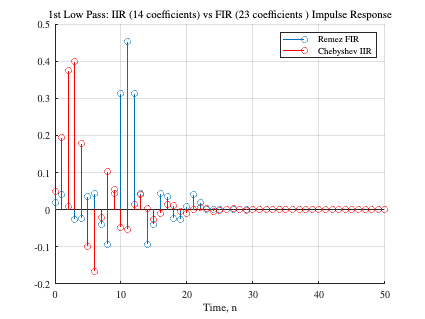

[~, b_remez, err] = remez_lowpass1([],fs);
[~, b_cheby, a_cheby] = low_pass1([],fs);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("1st Low Pass: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_Low_Pass_1_Impulse.eps", "-depsc");

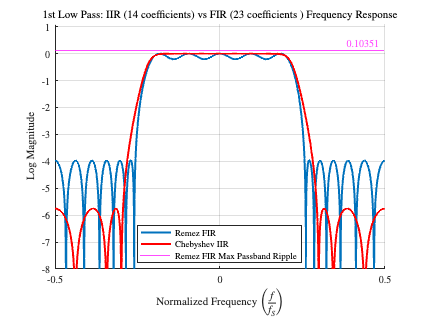


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("1st Low Pass: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_Low_Pass_1_Frequency.eps", "-depsc");

## 2nd Low Pass

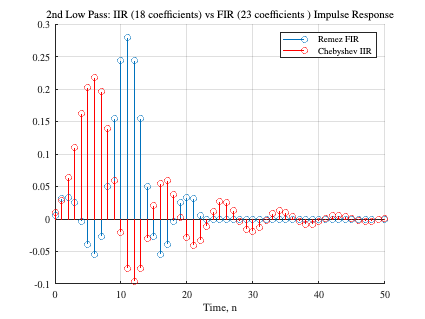

[~, b_remez, err] = remez_lowpass2([],fs);
[~, b_cheby, a_cheby] = low_pass2([],fs);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("2nd Low Pass: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_Low_Pass_2_Impulse.eps", "-depsc");

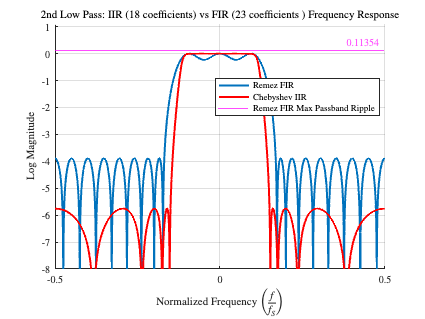


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("2nd Low Pass: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_Low_Pass_2_Frequency.eps", "-depsc");

## 1st High Pass

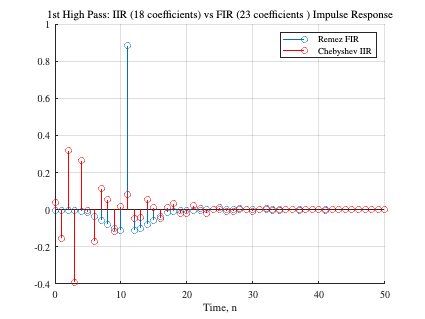

[~, b_remez, err] = remez_highpass1([],fs);
[~, b_cheby, a_cheby] = high_pass1([],fs);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("1st High Pass: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_High_Pass_1_Impulse.eps", "-depsc");

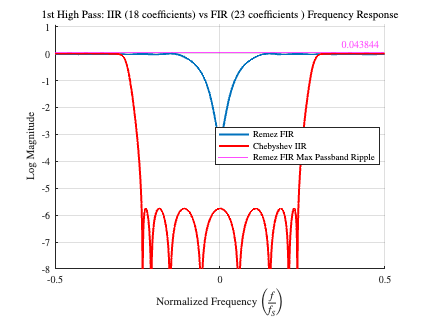


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("1st High Pass: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_High_Pass_1_Frequency.eps", "-depsc");

## Lo-f1

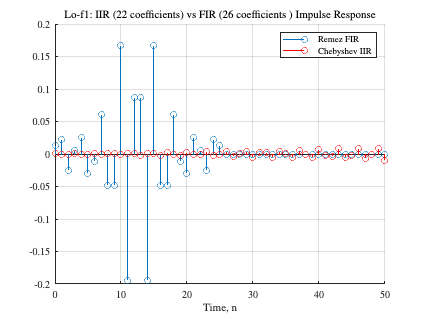

[~, b_remez, err] = remez_band_filter([],fs/4,677,717);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 677, 717, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Lo-f1: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_LoF1_Impulse.eps", "-depsc");

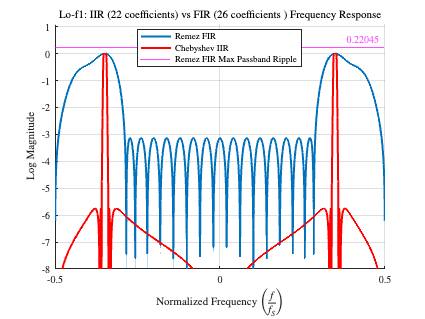


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Lo-f1: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_LoF1_Frequency.eps", "-depsc");

## Lo-f2

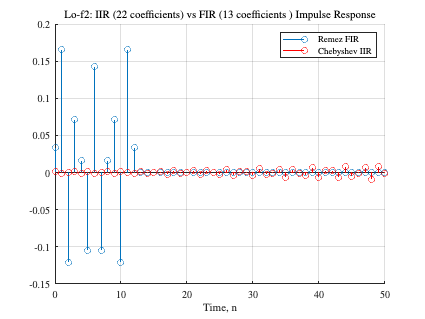

[~, b_remez, err] = remez_band_filter_special([],fs/4,750,790);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 750, 790, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Lo-f2: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_LoF2_Impulse.eps", "-depsc");

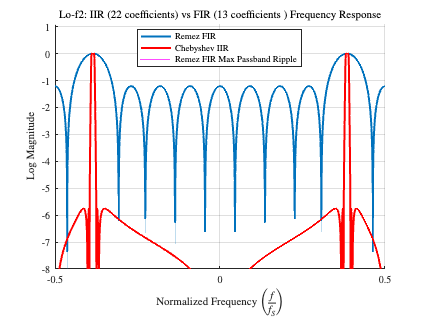


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Lo-f2: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_LoF2_Frequency.eps", "-depsc");

## Lo-f3

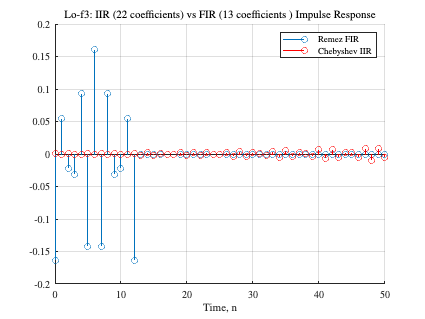

[~, b_remez, err] = remez_band_filter_special([],fs/4,832,872);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 832, 872, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Lo-f3: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_LoF3_Impulse.eps", "-depsc");

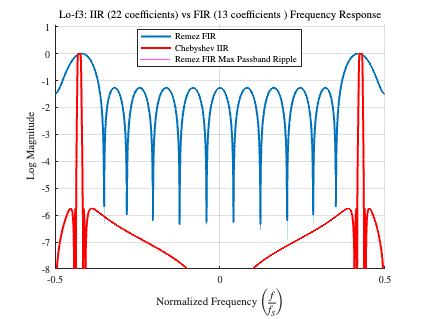


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Lo-f3: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_LoF3_Frequency.eps", "-depsc");

## Lo-f4

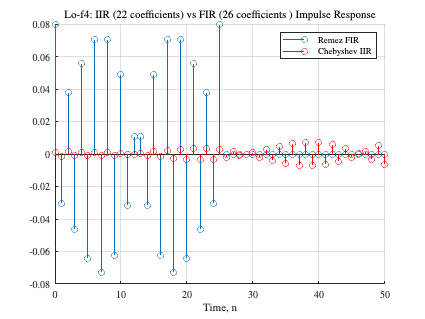

[~, b_remez, err] = remez_band_filter([],fs/4,921,961);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 921, 961, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Lo-f4: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_LoF4_Impulse.eps", "-depsc");

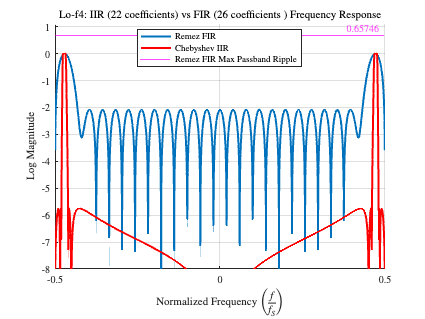


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Lo-f4: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_LoF4_Frequency.eps", "-depsc");

## Hi-f1

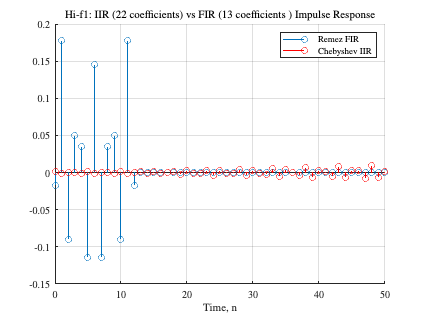

[~, b_remez, err] = remez_band_filter_special([],fs/4,770,810);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 770, 810, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Hi-f1: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_HiF1_Impulse.eps", "-depsc");

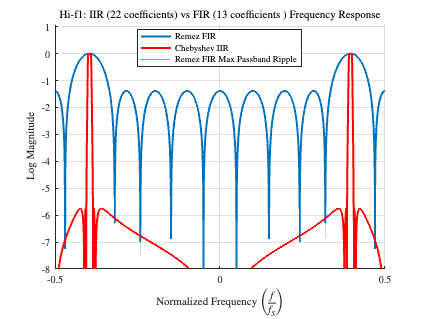


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Hi-f1: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_HiF1_Frequency.eps", "-depsc");

## Hi-f2

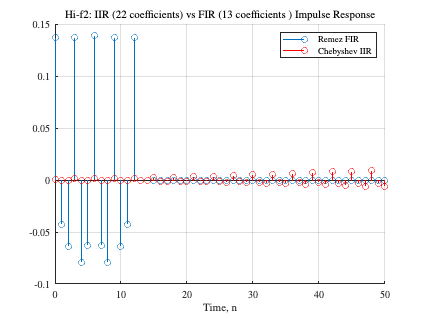

[~, b_remez, err] = remez_band_filter_special([],fs/4,645,685);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 645, 685, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Hi-f2: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_HiF2_Impulse.eps", "-depsc");

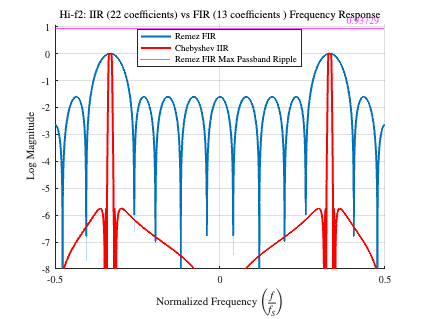


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Hi-f2: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_HiF2_Frequency.eps", "-depsc");

## Hi-f3

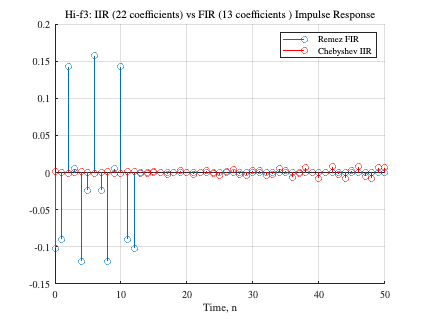

[~, b_remez, err] = remez_band_filter_special([],fs/4,505,545);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 505, 545, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Hi-f3: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_HiF3_Impulse.eps", "-depsc");

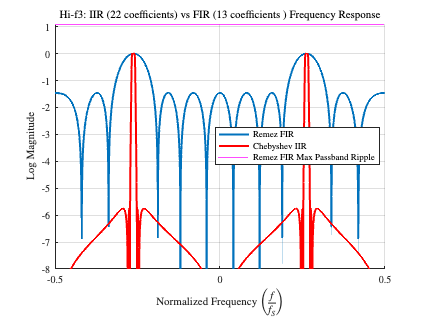


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Hi-f3: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_HiF3_Frequency.eps", "-depsc");

## Hi-f4

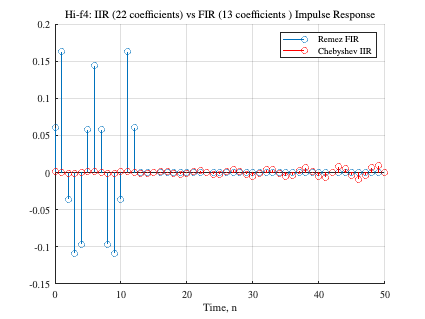

[~, b_remez, err] = remez_band_filter_special([],fs/4,350,390);
[~, b_cheby, a_cheby] = cheby2_HL_filter([], fs/4, filter_order, 350, 390, passband_ripple, stopband_attenuation);

remez_size = length(b_remez);
cheby_size = length(b_cheby) + length(a_cheby);

figure()
h_remez = filter(b_remez,1,delta);
h_cheby = filter(b_cheby,a_cheby,delta);
hold on
stem(0:1:(length(delta)-1),h_remez)
stem(0:1:(length(delta)-1),h_cheby, "Color","r")
title("Hi-f4: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Impulse Response")
xlabel("Time, n")
legend("Remez FIR", "Chebyshev IIR")
grid on
hold off

print("TeX/images/4H_HiF4_Impulse.eps", "-depsc");

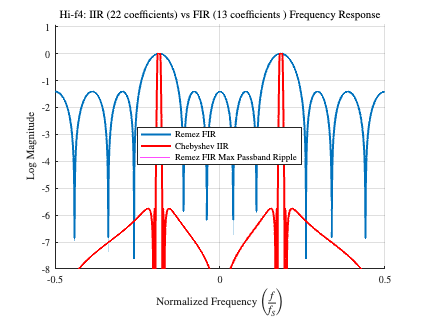


figure()
[H_remez,~]=freqz(b_remez,1,fs/4,"whole");
[H_cheby,~]=freqz(b_cheby,a_cheby,fs/4,"whole");
hold on
frq=(-0.5:1/(fs/4):0.5-1/(fs/4));
plot(frq,log(fftshift(abs(H_remez))/max(abs(H_remez))),"linewidth",2)
plot(frq,log(fftshift(abs(H_cheby))/max(abs(H_cheby))),"linewidth",2, "Color","r")
yline((err),"Color","m", "Label",string(err))
grid on
axis([-0.5 0.5 -8 1.1])
title("Hi-f4: IIR (" +cheby_size+" coefficients)  vs FIR (" + remez_size + " coefficients ) Frequency Response")
xlabel("Normalized Frequency $\left(\frac{f}{f_S}\right)$")
ylabel("Log Magnitude")
legend("Remez FIR", "Chebyshev IIR", "Remez FIR Max Passband Ripple", "Location","best")
hold off
print("TeX/images/4H_HiF4_Frequency.eps", "-depsc");